# Stationary test with the reverse-arrangement (RA) test and moving-window functions

In the present script the N-th order stationarity is used, following the definition of stationarity by Priestley [3]. Other types of non-stationarity are not discussed here. A stationary random process is characterized by statistical moments (mean, variance, kurtosis, skewness, etc...) that do not change with time. In the following, only the first and second-order stationarity are described. A random process is stationary at the first order if its mean does not change (significantly) with the time. Similarly, a random process is stationary at the second-order if its variance or standard deviation does not change (significantly) with the time. 

Assessing whether a random signal is stationary or not depends on the application one wishes to have. For wind turbulence data, the idea is to dismiss the time series if the non-stationary fluctuations introduce turbulence characteristics estimates with large error. Using simulated turbulence data, one could decide if the introduction of a trend in the data leads to acceptable or unacceptable non-stationary fluctuations. Note that for turbulence fluctuations, the second-order stationarity has also been defined in terms of covariance [4]. However, the method by ref [4] is not recommended because covariance estimates are also associated with a large random error. In ref [4], the random error was larger than the threshold value used to classify the records as stationary or not. This led to an excessive number of data removed.

The stationarity of simulated turbulent velocity data is assessed using two different approaches:

- A non-parametric test [2], which detects trends and classifies the time series as non-stationary if the trend is not negligible.

- A parametric test based on moving-window functions that compares the instantaneous mean or standard deviation to the one obtained without any detrending.

In the following, three examples are considered:

- A simple verification of the reverse arrangement test [2].

- The assessment of the first and second-order stationarity of turbulence data with linear trends: light, moderate and strong trend.

- The assessment of the first and second-order stationarity of turbulence data with a non-linear trend: light, moderate and strong trend.

To run the examples, you will need some additional functions:

- randomProcess.m, available on [https://se.mathworks.com/matlabcentral/fileexchange/76854-one-point-random-process-generation](https://se.mathworks.com/matlabcentral/fileexchange/76854-one-point-random-process-generation) 

- getSamplingPara.m, available on [https://se.mathworks.com/matlabcentral/fileexchange/76854-one-point-random-process-generation](https://se.mathworks.com/matlabcentral/fileexchange/76854-one-point-random-process-generation) 

- binAveraging.m, available on [https://se.mathworks.com/matlabcentral/fileexchange/73584-averaging-noisy-data-into-bins](https://se.mathworks.com/matlabcentral/fileexchange/73584-averaging-noisy-data-into-bins)  

**References**

[1] Kaimal, J. C., & Finnigan, J. J. (1994). *Atmospheric boundary layer flows: their structure and measurement*. Oxford university press.

[2] Bendat and piersol, Random data, 2010, page 99

[3] *Priestley, M. B. (1981). **Spectral Analysis and Time Series**. Academic Press. *[*ISBN*](https://en.wikipedia.org/wiki/ISBN_(identifier)) [*0-12-564922-3*](https://en.wikipedia.org/wiki/Special:BookSources/0-12-564922-3)*.*

*[4] *Foken, T., & Wichura, B. (1996). Tools for quality assessment of surface-based flux measurements. *Agricultural and forest meteorology*, *78*(1-2), 83-105.

## Verification of the function RA_test: reproduction of an example from Bendat and piersol [2]

The example is based on the book by Bendat and piersol [2]

clearvars;close all;clc;
data = [5.2,6.2,3.7,6.4,3.9,4.0,3.9,5.3,4,4.6,5.9,6.5,4.3,5.7,3.1,5.6,5.2,3.9,6.2,5.0];
[ResultTest,A,Ainf,Asup] = RA_test(data,1);
disp([ResultTest,A,Ainf,Asup]) % These are the same number as in [2]

     1    86    65   125



## Case of a  Gaussian random process

### Data preparation: Generation of turbulent velocity data

In this section, the target spectral density used is the Kaimal turbulence model for the along-wind component [1]. 

clearvars;close all;clc;
rng(1); % for reproducibility only. Comment this line otherwise.
fs = 35; % sampling frequency (in Hertz)
M = 17; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs); % Get the frequency and time vector

Duration of target time series is 1.04 hours, i.e. 3.74e+03 sec 




% parameters used wih the Kaimal spectrum
u_star = 0.4; % Friction velocity
meanU = 10; % mean wind speed
z = 40; % measurement height
fr = f.*z/meanU; % reduced frequency

S = u_star.^2./f.*102.*fr./(1+33.*fr).^(5/3); % Target PSD

if exist('randomProcess','file')
    tic
    [u,~] = randomProcess(f,S);
    toc
    fprintf(['Turbulence intensity is ',num2str(std(detrend(u)./meanU),3),' \n'])
    
else
    error('The function "randomProcess" is not found. You can find it here: https://se.mathworks.com/matlabcentral/fileexchange/76854-one-point-random-process-generation')
end

Elapsed time is 0.010476 seconds.


Turbulence intensity is 0.0844 


u = u+meanU;

### Samples with a linear trend

It can be tricky to attempt to correct the mean wind speed for the linear trend. It may simpler to dismiss the data if the fluctuations are found to be non-stationary. However, the higher-order non-stationary fluctuations introduced by a linear trend can be corrected by simply using the function "detrend". You can check using "std(detrend(u1(4,:)))./std(u1(1,:))-1", which will lead to a negligible relative difference with the case where no trend was used. 

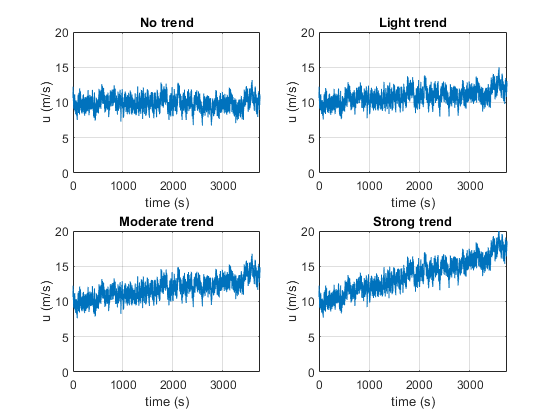

clear u1
myLabel = {'No trend','Light trend','Moderate trend','Strong trend'};
u1(1,:)=u;
u1(2,:) = u + 0.0005.*t'; % light trend
u1(3,:) = u + 0.001.*t'; % moderate trend
u1(4,:) = u + 0.002.*t'; % strong trend

figure
for ii=1:4
    subplot(2,2,ii)
    plot(t,u1(ii,:))
    grid on
    title(myLabel{ii})
    ylabel('u (m/s)')
    xlabel('time (s)')
    axis tight
    ylim([0,20])
end



err_meanU = round(100.*(mean(u1,2)./mean(u1(1,:))-1)); %relative error on the mean
err_stdU = round(100.*(std(u1,0,2)./std(u1(1,:))-1)); %relative error on the mean
T = table(err_meanU,err_stdU);
T.Properties.RowNames = myLabel;
disp(T)

                      err_meanU    err_stdU
                      _________    ________

    No trend              0            0   
    Light trend           9           18   
    Moderate trend       19           61   
    Strong trend         38          173   



### Samples with a Non-linear trend

The non-linear trend can be responsible for no error on the mean wind speed but a large error on the variance of the signal. In that case, removing the linear trend won't be useful. It may simpler to dismiss the data if the fluctuations are found to be non-stationary.

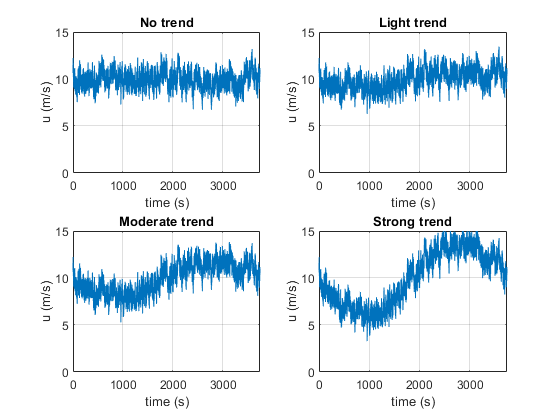

clear u2
myLabel = {'No trend','Light trend','Moderate trend','Strong trend'};
u2(1,:)=u;
u2(2,:) = u - 0.1*meanU.*sin(2*pi.*t./t(end))'; % light trend
u2(3,:) = u - 0.2*meanU.*sin(2*pi.*t./t(end))'; % light trend
u2(4,:) = u - 0.4*meanU.*sin(2*pi.*t./t(end))'; % light trend

figure
set(gcf,'color','w')
for ii=1:4
    subplot(2,2,ii)
    plot(t,u2(ii,:))
    grid on
    title(myLabel{ii})
    ylabel('u (m/s)')
    xlabel('time (s)')
    axis tight
    ylim([0,15])
end

err_meanU = round(100.*(mean(u2,2)./mean(u2(1,:))-1)); %relative error on the mean
err_stdU = round(100.*(std(u2,0,2)./std(u2(1,:))-1)); %relative error on the mean

T = table(err_meanU,err_stdU);
T.Properties.RowNames = myLabel;
disp(T)

                      err_meanU    err_stdU
                      _________    ________

    No trend              0            0   
    Light trend           0           21   
    Moderate trend        0           82   
    Strong trend          0          235   



## First and second-order stationarity for the case of a linear trend

The RA test is not a parametric test. For the varable "u1", which contains a linear trend, we would like the time series to be considered as stationary if the relative error on the mean wind speed or the standard deviation is below 10%. That means that the case with a "light trend" should still be considered as stationary. Howeverm the cases with a moderate and strong trend will not be consdiered as stationary. The RA test will detect the trend and classify the time series as non-stationary. For the purpose of velocity records, this may be lead to the removal of too much data since the light trend was also detected as non-stationary.

### Application of the reverse-arrangement test

method = 2; % I personnaly prefer the method "2" by Siegel and Castellan,1988
binWidth = 300;  % Data are bin-averaged into bins of 5 minutes, i.e. 300 seconds

for ii=1:4
    % We compute the mean wind speed in a limited number of sub-segments
    if exist('binAveraging','file')
        [u_binned,~,stdU_binned] = binAveraging(u1(ii,:),t,'binWidth',binWidth);
    else
        error('The function "binAveraging" is not found. You can find it here: https://se.mathworks.com/matlabcentral/fileexchange/73584-averaging-noisy-data-into-bins')
    end
    
    [result_O1,A,Ainf,Asup] = RA_test(u_binned,method); % First-order stationary test
    [result_O2,A,Ainf,Asup] = RA_test(stdU_binned,method); % Second-order stationary test
    
    if result_O1==1 && result_O2==1
        fprintf(['The time series with ', myLabel{ii},' is stationary according to the RA test \n']);
    else
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary according to the RA test \n']);
    end
end

The time series with No trend is stationary according to the RA test 


The time series with Light trend is NOT stationary according to the RA test 
The time series with Moderate trend is NOT stationary according to the RA test 
The time series with Strong trend is NOT stationary according to the RA test 


fprintf('\n\n')

### Application of the moving-window function

The moving window is a parametric test, which allows the user to decide how much non-stationary fluctuations is acceptable. Let's say that, in the following, one wish to keep the data with a light trend as "stationary". In that case, the threshold value for the first-order stationarity (threshold1) can be equal to 0.18 and for the second-order stationarity, the second threshold (threshold2) is 0.4. 

windowLength = round(binWidth*fs); % Number of windows for the moving windows function. Here the windows are also 300 sec
threshold1 = 0.20; % Threshold for the first-order stationarity (user-defined)
threshold2 = 0.40; % Threshold for the second-order stationarity  (user-defined)
for ii=1:4
    [Result,Err1,Err2] = MW_test(u1(ii,:),windowLength,threshold1,threshold2);
    if Result==1,
        fprintf(['The time series with ', myLabel{ii},' is stationary at the first order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1>threshold1 && Err2<threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the first order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1<threshold1 && Err2>threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the second order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1>threshold1 && Err2>threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the first AND second order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    else
        error('Something went wrong')
    end
end

The time series with No trend is stationary at the first order. Err1 = 0.069. Err2 = 0.31 


The time series with Light trend is NOT stationary at the second order. Err1 = 0.14. Err2 = 0.4 


The time series with Moderate trend is NOT stationary at the first AND second order. Err1 = 0.21. Err2 = 0.56 
The time series with Strong trend is NOT stationary at the first AND second order. Err1 = 0.31. Err2 = 0.74 


fprintf('\n\n')

## First and second-order stationarity for the case of a non-linear trend

### Application of the reverse-arrangement test

The RA test is a trend test, so it does not perform very well to detect the non-linear trend introduced in the time series. Nevertheless, it still performs relatively well for the first-order stationarity as it detects the non-linear trend.

method = 2; % I personnaly prefer the method "2" by Siegel and Castellan,1988
binWidth = 300;  % Data are bin-averaged into bins of 5 minutes, i.e. 300 seconds

for ii=1:4
    % We compute the mean wind speed in a limited number of sub-segments
    if exist('binAveraging','file')
        [u_binned,~,stdU_binned] = binAveraging(u2(ii,:),t,'binWidth',binWidth);
    else
        error('The function "binAveraging" is not found. You can find it here: https://se.mathworks.com/matlabcentral/fileexchange/73584-averaging-noisy-data-into-bins')
    end
    
    [result_O1,A,Ainf,Asup] = RA_test(u_binned,method); % First-order stationary test
    [result_O2,A,Ainf,Asup] = RA_test(stdU_binned,method); % Second-order stationary test
    if result_O1==1 && result_O2==1
        fprintf(['The time series with ', myLabel{ii},' is stationary at the first and second order, according to the RA test \n']);
    elseif result_O1==0 && result_O2==1
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the first order according to the RA test \n']);
    elseif result_O1==1 && result_O2==0
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the second order according to the RA test \n']);
    elseif result_O1==0 && result_O2==0
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary according to the RA test \n']);
    end
end

The time series with No trend is stationary at the first and second order, according to the RA test 


The time series with Light trend is NOT stationary at the first order according to the RA test 
The time series with Moderate trend is NOT stationary at the first order according to the RA test 
The time series with Strong trend is NOT stationary at the first order according to the RA test 


fprintf('\n\n')

### Application of the moving-window function

windowLength = round(binWidth*fs); % Number of windows for the moving windows function. Here the windows are also 300 sec
threshold1 = 0.20; % Threshold for the first-order stationarity (user-defined)
threshold2 = 0.40; % Threshold for the second-order stationarity  (user-defined)
for ii=1:4
    [Result,Err1,Err2] = MW_test(u2(ii,:),windowLength,threshold1,threshold2);
    if Result==1
        fprintf(['The time series with ', myLabel{ii},' is stationary at the first order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1>threshold1 && Err2<threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the first order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1<threshold1 && Err2>threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the second order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    elseif Err1>threshold1 && Err2>threshold2
        fprintf(['The time series with ', myLabel{ii},' is NOT stationary at the first AND second order. Err1 = ',num2str(Err1,2),'. Err2 = ',num2str(Err2,2),' \n']);
    else
        error('Something went wrong')
    end
end

The time series with No trend is stationary at the first order. Err1 = 0.069. Err2 = 0.31 


The time series with Light trend is NOT stationary at the second order. Err1 = 0.11. Err2 = 0.41 
The time series with Moderate trend is NOT stationary at the second order. Err1 = 0.2. Err2 = 0.61 


The time series with Strong trend is NOT stationary at the first AND second order. Err1 = 0.4. Err2 = 0.79 
